
========== CARP MISSION PLANNING ==========
CARP Predictions (Dual G-12D System):
  Forward Travel Distance: 563.40 yards (515.17 m)
  Drift Effect:            39.88 yards (36.46 m)
  Total Time of Fall:      7.10 sec
  Ground Speed:            145.34 knots (74.77 m/s)
  Rate of Fall:            20.03 ft/s (6.10 m/s)

========== SINGLE G-12D PARACHUTE (REALISTIC) ==========
  Diameter:             19.51 m (64.00 ft)
  Reference Area:       298.87 m²
  Mass:                 57.00 kg (125.66 lb)
  Riser Length:         18.28 m (59.97 ft)
  Riser Stiffness:      26000 N/m
  Riser Damping:        700 N·s/m
  Canopy Efficiency:    0.90 (REALISTIC)
  Canopy Porosity:      15.0% (REALISTIC)

Expected Performance:
  Total system mass:    601.31 kg (1325.66 lb)
  Total weight:         5898.86 N (1326.18 lbf)
  Effective CdS:        388.68 m²
  Calculated V_terminal:    4.98 m/s (16.33 ft/s)
  CARP RoF target:      6.10 m/s (20.0 ft/s)


========== TRAJECTORY ANALYSIS ==========
Configuration: 1 × G-12D Parachutes
Simulation Info:
  Total time steps: 2000
  State vector dim: 26
  Max time:         40.00 sec

Propagator Trajectory:
  Initial altitude:     121.92 m (400.00 ft)
  Final altitude:       -0.20 m (-0.66 ft)
  Altitude descended:   122.12 m (400.66 ft)
  Mean descent rate:    18.38 m/s (60.31 ft/s)
  Terminal descent:     9.44 m/s (30.97 ft/s)
  Mean horiz velocity:  75.40 m/s (146.57 knots)
  Landing time:         6.64 sec
  East displacement:    -426.06 m
  North displacement:   263.25 m
  Total horiz distance: 500.83 m (547.71 yards)

========== HORIZONTAL VELOCITY ANALYSIS ==========
Initial Conditions:
  Initial horiz vel (ENU): 74.77 m/s (145.34 knots)
  Expected ground speed:    74.77 m/s (145.34 knots)

Velocity Decay:
  Initial horiz vel:  74.77 m/s
  Final horiz vel:    77.21 m/s
  Velocity lost:      -2.44 m/s (-3.3%)
  Mean horiz vel:     75.40 m/s

Horizontal Distance Analysis:
  Actual distance:

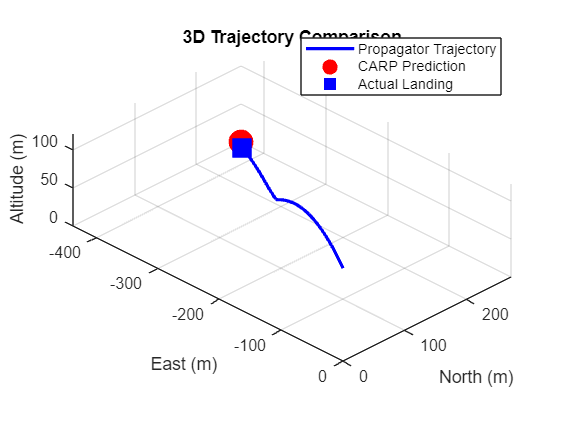

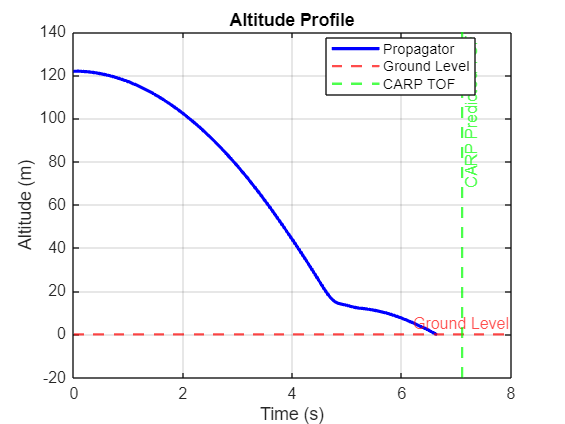

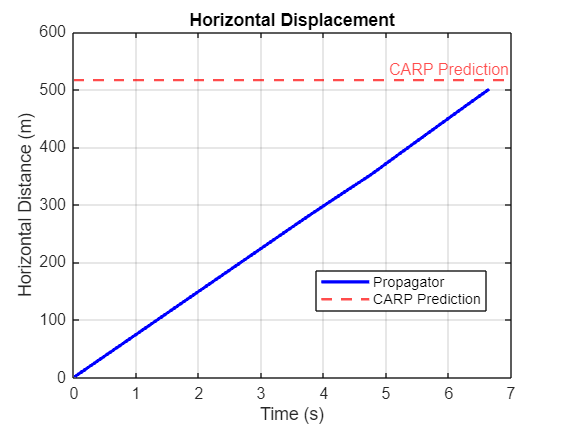

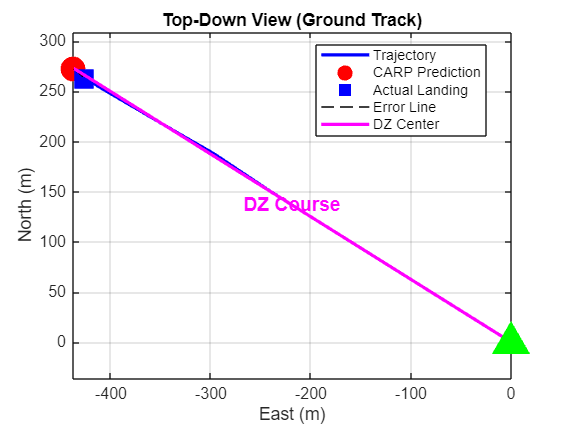

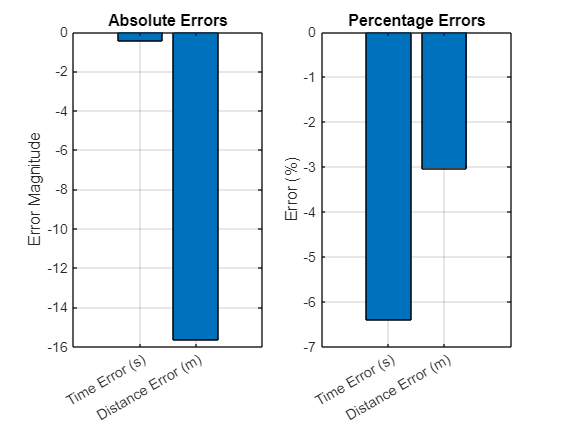

clear all;

close all;
clc;

results = validate_carp_vs_propagatorV2('drop_altitude', 400,'terrain_elevation', 560, 'ballistic_wind', 10, 'drop_altitude_wind', 15,'dz_altimeter', 29.85, 'surface_temperature', 20, 'true_altitude_temperature', 15, 'DZ_course', 302, 'indicated_airspeed', 130,'num_parachutes', 1,'parachute_deploy_time', 3.38,'visualize', true);
